# **Explore the Discrete time Kalman filter      **

In this example we're going to study the two degree of freedom (dof)  mechanical system shown below:

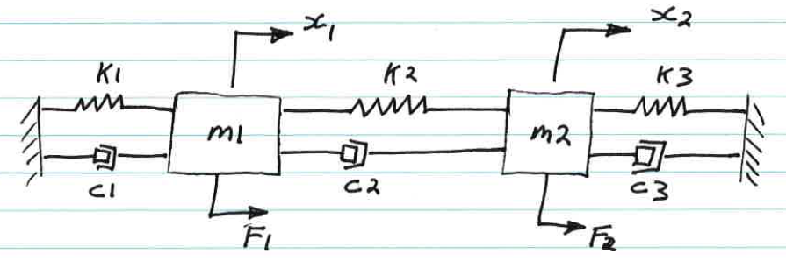 

In this tutorial we're going to look at the following subtopics:

- apply Newton's laws to derive the system's dynamic equation of motion

- solve **NUMERICALLY** the solution for the excitation case involving STEP functions

- explore the Discrete Time Kalman filter

`Bradley Horton : 07-Jul-2017, bradley.horton@mathworks.com.au`

**Apply Newton's law:**

The free body diagram for this system is shown below:

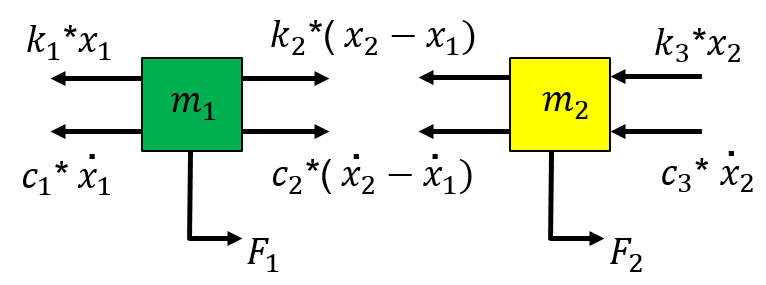

For the 1st mass we have:


$$m_1 \thinspace \ddot{x_1} = F_1 + k_2(x_2 - x_1) + c_2(\dot{x_2} - \dot{x_1}) - k_1x_1 - c_1 \dot{x_1}$$
 


$$m_1 \thinspace \ddot{x_1} = F_1  +  x_1(-k_2 + -k_1) +   x_2(k_2) +  \dot{x_1}(-c_2 + -c_1) +   \dot{x_2} (c_2) 
$$
 

For the 2nd mass we have:


$$m_2 \thinspace \ddot{x_2} = F_2 - k_2(x_2 - x_1) - c_2(\dot{x_2} - \dot{x_1}) - k_3x_2 - c_3 \dot{x_2}$$


 
$$m_2 \thinspace \ddot{x_2} = F_2  +  x_1(k_2) + x_2(-k_2 + -k_3) + \dot{x_1}(c_2) + \dot{x_2}(-c_2 + -c_3)$$


We can combine the two 2nd order ODEs into a matrix equation, ie:

$\pmatrix{
m_1 & 0 \cr
0 & m_2 \cr
}$$. \pmatrix{
\ddot{x}_1 \cr
\ddot{x}_2 \cr
}$ + $\pmatrix{
(c_1 + c_2) & -c_2 \cr
-c_2 & (c_2+c_3) \cr
}$$. \pmatrix{
\dot{x}_1 \cr
\dot{x}_2 \cr
}$ + $\pmatrix{
(k_1 + k_2) & -k_2 \cr
-k_2 & (k_2+k_3) \cr
}$$. \pmatrix{
{x}_1 \cr
{x}_2 \cr
}$= $\pmatrix{
{F}_1 \cr
{F}_2 \cr
}$

which we can refer to as:   

- $M \ddot{X} + C\dot{X} + KX = F$   where   $X \in R^{n\times1}$

**Define the Mechanical system parameters and system matrices:**

Note all parameters are in SI units, ie: *kg, N/m, N/(m/sec)*

params = bh_func_2dof_params();

m1 = params.m1 ;    m2 = params.m2 ; 
k1 = params.k1 ;    k2 = params.k2 ;    k3 = params.k3 ;
c1 = params.c1 ;    c2 = params.c2 ;    c3 = params.c3 ;


So the system matrices are:

Mm_mat  = [m1, 0;
            0,   m2  ];

Km_mat  = [(k1+k2),   -k2;
              -k2,    (k2+k3) ];

Cm_mat  = [(c1+c2), -c2;
           -c2,    (c2+c3) ];

**Define the INITIAL conditions of the system:**

Let's consider the system with the following initial conditions - all parameters are in SI units, ie: *(m) *and *(m/sec)*

- $\dot{x_1 } \left(0\right)=0$,     $x_1 \left(0\right)=\text{ }\text{ }1\text{ }$ 

- $\dot{x_2 } \left(0\right)=5$,     $x_2 \left(0\right)=-0\ldotp 5$  

init_x1dot =  0;     init_x1    =  1;
init_x2dot =  5;     init_x2    = -0.5;

## Define our system Excitation functions:

We'll create 2 function handles for our excitation forces:

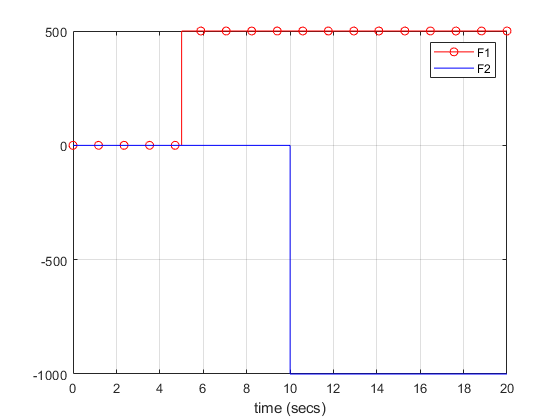

F1_fh  = @(t)    500*heaviside(t-5);
F2_fh  = @(t)  -1000*heaviside(t-10);

% visualise them
figure
    fplot(F1_fh, [-0.01, 20], '-ro');  hold on
    fplot(F2_fh, [-0.01, 20], '-b');  
    
    legend({'F1','F2'}); 
    xlabel('time (secs)'); grid('on')

# Numerical solution:

At the heart of this approach are MATLAB's ODE solver suite - MATLAB has many ODE solver algorithms.  A good general purpose solver is the MATLAB function `ode45()` .  These numeric ODE solvers require you to package your problem into a 1st order form. 

- $\dot{y} =f\left(t,y\right)$     or     $M\left(t,y\right)\ldotp \dot{y} =f\left(t,y\right)$

For our Mechanical system we can write our system equation as:

- $\pmatrix{
M & 0_{n \times n} \cr
0_{n \times n} &  I_{n \times n} \cr
} .$$\pmatrix{
\ddot{X} \cr
\dot{X} \cr
}$  +  $\pmatrix{
C & K \cr
-I_{n \times n} &  0_{n \times n} \cr
} $$. \pmatrix{
\dot{X} \cr
X \cr
}$ $= 
\pmatrix{
F \cr
0 \cr
}$

Which can then be rearranged into the following form:

                      $\pmatrix{
\ddot{X} \cr
\dot{X} \cr
}$ = $\pmatrix{
-M^{-1}C & -M^{-1}K \cr
I_{n \times n} & 0_{n \times n} \cr
}$$. \pmatrix{
\dot{X} \cr
X \cr
}$  +  $\pmatrix{
M^{-1}{F} \cr
0_{n \times 1} \cr
}$

which has the form:

                  $\dot{Z} = A . Z + G$    where:  $Z =  \pmatrix{
\dot{X} \cr
X \cr
} \in R^{2n \times 1}$   and    $G = \pmatrix{
M^{-1}{F} \cr
0_{n \times 1} \cr
}$    and    $A = \pmatrix{
-M^{-1}{C} & -M^{-1}{K}\cr
I_{n \times n} & 0_{n \times n} \cr
}$

I've implemented these equations in the MATLAB function `bh_mech_system()`:

dbtype bh_mech_system.m  


1     function dZdt_col = bh_mech_system( Mass_mat,   ...
2                                         Kstiff_mat, ...
3                                         Cdamp_mat,  ...
4                                         Fh,         ...
5                                         t,          ...
6                                         Z_col )
7        % M_mat  is  n_x_n
8        % Fh     is  1_x_1 that returns an n_x_1
9        % Z_col  is 2n_x_1
10       % ---------------------------------------------------------------------
11       %  M.XDD + C.XD + K.X = F
12       %
13       %  [ M 0 ].(XDD)  +  [C  K].(XD)  = (F)  
14       %  [ 0 I ] (XD )     [-I 0] (X )    (0)
15       %
16       %          (XDD)   = [-inv(M)*C, -inv(M)*K].[XD]   +  [inv(M)*F] 
17       %          (XD )     [        I,     0    ] [X]       [   0    ]
18       %
19       %           ZD     =   A * Z + G
20       %
21       %  where:        Z = [XD] = [x1_dot] 
22       %                    [X ]   [x2_dot]
23       

So let's look at the example we solved previously:

% Define your INITIAL conditions
z_init = [init_x1dot;
          init_x2dot;
          init_x1;
          init_x2 ];

% define the system EXCITATION functions
Fsys_fh    = @(t) [  F1_fh(t); 
                     F2_fh(t) ];

% define the 1st order system to solve
MY_SYSTEM = @(t, z) bh_mech_system(Mm_mat, Km_mat, Cm_mat, Fsys_fh, t, z);

% Define some ODE solver settings
Ts         = 0.01;
t_span     = [0:Ts:15];
my_options = odeset('RelTol', 1e-7, 'AbsTol', 1e-7);

% use ODE45 to numerically solve your system
%[T,Y] = solver(odefun,   tspan,  z0,     options)
[T,Z]  = ode45(MY_SYSTEM, t_span, z_init, my_options);

## Extract and rename states:

x1_dot   = Z(:,1); 
x2_dot   = Z(:,2);  
x1       = Z(:,3);  
x2       = Z(:,4);
t        = T;

## Plot the NOISE free NUMERIC solution:

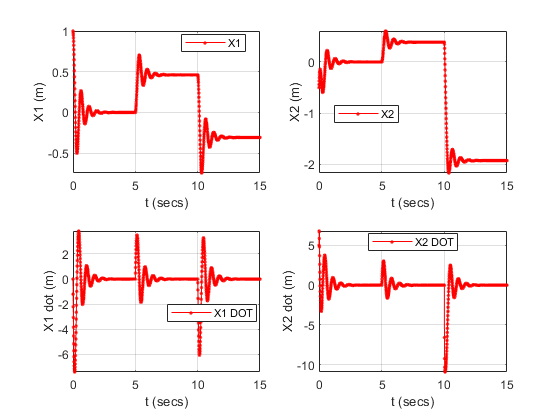

LOC_plot_states(t, x1, x2, x1_dot, x2_dot)

# **Explore the Discrete time Kalman Filter:**

## Define CLEAN data:

y_meas_clean = [x1';
                x2'; ];       % a 2_x_N matrix
            
u_clean_mat = [F1_fh(t)';
               F2_fh(t)' ];   % a 2_x_N matrix

## Define NOISY measurement data:

y_meas_mat  =  y_meas_clean  +  sqrt(0.1)*randn ( size(y_meas_clean)  );

Plot the clean and NOISY measurement data:

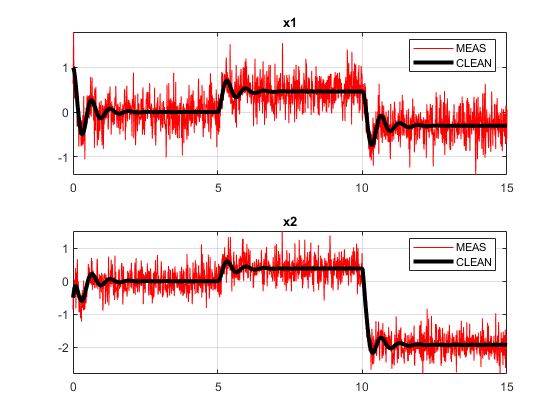

figure;
subplot(2,1,1);
    plot(t,   y_meas_mat(1,:), '-r'); hold on
    plot(t, y_meas_clean(1,:), '-k', 'LineWidth',3);
    grid on, axis tight
    legend(["MEAS", "CLEAN"],'Location','Best')
    title(gca, 'x1')
subplot(2,1,2);
    plot(t,   y_meas_mat(2,:), '-r'); hold on
    plot(t, y_meas_clean(2,:), '-k', 'LineWidth',3);
    grid on, axis tight
    legend(["MEAS", "CLEAN"],'Location','Best')
    title(gca, 'x2')    

**Create the state space system model neded by our Filter:**

For our Mechanical system we can write it in state space form as:

                      $\pmatrix{
\ddot{X} \cr
\dot{X} \cr
}$ = $\pmatrix{
-M^{-1}C & -M^{-1}K \cr
I_{n \times n} & 0_{n \times n} \cr
}$$. \pmatrix{
\dot{X} \cr
X \cr
}$  +  $\pmatrix{
M^{-1} \cr
0_{n \times 1} \cr
}.F$

which has the form:

                  
$$\dot{Z} = A . Z + B.u$$
    

where:  $Z =  \pmatrix{
\dot{X} \cr
X \cr
} \in R^{2n \times 1}$   and   $u =  F \in R^{n \times 1}$   and    $B = \pmatrix{
M^{-1} \cr
0_{n \times 1} \cr
}$    and    $A = \pmatrix{
-M^{-1}{C} & -M^{-1}{K}\cr
I_{n \times n} & 0_{n \times n} \cr
}$

Ac = [-inv(Mm_mat)*Cm_mat, -inv(Mm_mat)*Km_mat;
                   eye(2),     zeros(2)   ];
Bc = [inv(Mm_mat);
       zeros(2);];

Note the "channels" that we're measuring:  it's $x_1$ and $x_2$:


$$C=\left\lbrack \begin{array}{cccc}
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
\dot{x_1 } \\
\dot{x_2 } \\
x_1 \\
x_2 
\end{array}\right\rbrack$$
  

Cc = [0, 0, 1, 0;
      0, 0, 0, 1 ];

Create the CONTINUOUS state space model:

ss_cont = ss(Ac,Bc,Cc,[]);

Convert continuous model to a DISCRETE model:

ss_disc = c2d(ss_cont,Ts);

So the Discrete State Space system is:

Ad = ss_disc.A;
Bd = ss_disc.B;
Cd = ss_disc.C;

## Use the Kalman filter in BATCH mode:

x0 = [0,0,2,2]';
P0 = diag([1,1,1,1]).^2;   % covariance matrix of state estimate
Q  = diag([1,1,1,1]);      % process noise covariance matrix
R  = diag([77,77]);        % measurement noise covariance matrix

OBJ = my_KF_general_CLS( Ad, Bd, Cd, Q, R, x0, P0 );

Say our original $U_{\mathrm{ORIG}}$ and $Y_{\text{ORIG}}$ have the following attributes:

- 
$$U_{\text{ORIG}} \text{  }$$
 
$$\text{ }=\text{ }\left\lbrack u_0 ,\text{ }u_1 ,{\text{ }u}_2 ,{\text{ }u}_3 ,\text{ }\ldotp \ldotp \ldotp u_{\text{Ns}-1} \right\rbrack$$
   
$$\varepsilon \text{   }\text{Nu}\times \text{Ns}$$


- 
$$Y_{\text{ORIG}} \text{  }$$
   
$$=\text{ }\left\lbrack \text{ }y_0 ,\text{ }y_1 ,{\text{ }y}_2 ,\text{ }y_3 ,\text{ }\ldotp \ldotp \ldotp y_{\text{Ns}-1} \right\rbrack$$
    
$$\varepsilon \text{   }\mathrm{N}y\times \text{Ns}$$
 

Now for our filtering task, define U and Y matrices according to:

- 
$$U=\left\lbrack u_0 ,\text{ }u_1 ,{\text{ }u}_2 ,{\text{ }u}_3 ,\text{ }\ldotp \ldotp \ldotp u_{\mathrm{Ns}-2} \right\rbrack$$
   
$$\varepsilon \text{   }\text{Nu}\times \left(\mathrm{Ns}-1\right)$$


- 
$$Y=\left\lbrack \text{ }y_1 ,{\text{ }y}_2 ,\text{ }y_3 ,{\text{ }y}_4 ,\text{ }\ldotp \ldotp \ldotp u_{\mathrm{Ns}-1} \right\rbrack$$
   
$$\varepsilon \text{   }\text{N}y\times \left(\text{Ns}-1\right)$$


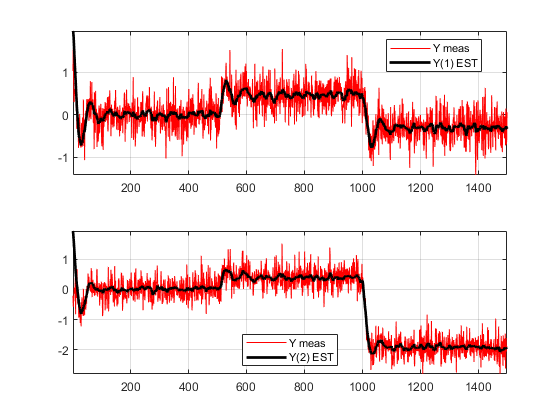

U_0_to_Nm1 = u_clean_mat(:,1:(end-1));
Y_1_to_N   =  y_meas_mat(:,2:end);

%>> [xo_mat, yo_mat, hax] = OBJ.batch_step(u_mat,       y_mat,     tf_do_plots) 
    [xo_mat, yo_mat, hax] = OBJ.batch_step(U_0_to_Nm1,  Y_1_to_N,  true);

For comparison, add our true (CLEAN) state values to the Kalman estimate plots - note we add the CLEAN data starting at $t=t_1$ and not $t=t_0$

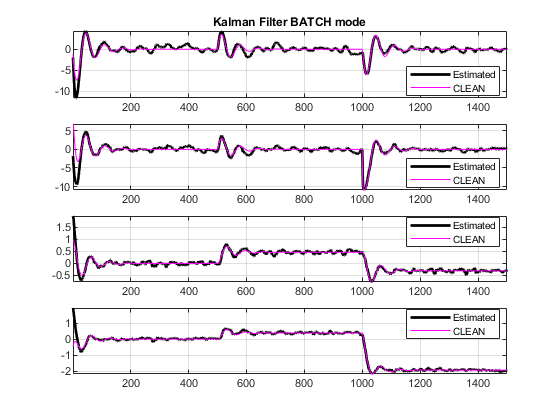

ans =   Legend (Y meas, Y(2) EST) with properties:

         String: {'Y meas'  'Y(2) EST'}
       Location: 'best'
    Orientation: 'vertical'
       FontSize: 8.1000
       Position: [0.4318 0.1282 0.1714 0.0774]
          Units: 'normalized'

  Show all properties


hold(hax(1), 'on');   plot(hax(1), x1_dot(2:(end-1)), '-m');   legend(hax(1), {'Estimated','CLEAN'},'Location','Best');
hold(hax(2), 'on');   plot(hax(2), x2_dot(2:(end-1)), '-m');   legend(hax(2), {'Estimated','CLEAN'},'Location','Best');
hold(hax(3), 'on');   plot(hax(3),     x1(2:(end-1)), '-m');   legend(hax(3), {'Estimated','CLEAN'},'Location','Best');
hold(hax(4), 'on');   plot(hax(4),     x2(2:(end-1)), '-m');   legend(hax(4), {'Estimated','CLEAN'},'Location','Best');

title(hax(1), 'Kalman Filter BATCH mode');  legend()

## We could also use the Kalman filter in STEP-by-STEP mode:

clear OBJ

OBJ = my_KF_general_CLS( Ad, Bd, Cd, Q, R, x0, P0 );

% preallocate a matrix to store our xk (NOT including x0)
big_X      = zeros(length(x0),  size(Y_1_to_N, 2));

for kk=1:length(Y_1_to_N)
    
    u_k_minus_1 = U_0_to_Nm1(:,kk);
    y_k         =   Y_1_to_N(:,kk);
    
   % make prediction of x_k 
   OBJ = OBJ.predict(u_k_minus_1);
   
   % use measurement at t=k to correct the estimate of xk
   OBJ = OBJ.correct(y_k);
   
   % retrieve state vector xk
   xk = OBJ.get_state();
   
   % insert xk into the results matrix.
   big_X(:,kk) = xk;
end

Now plot the states estimated by the Kalman filter:

figure;
hax(1) = subplot(4,1,1);  plot( big_X(1,:), '-k', 'LineWidth',2); grid('on'); axis('tight');
hax(2) = subplot(4,1,2);  plot( big_X(2,:), '-k', 'LineWidth',2); axis('tight');
hax(3) = subplot(4,1,3);  plot( big_X(3,:), '-k', 'LineWidth',2); axis('tight');
hax(4) = subplot(4,1,4);  plot( big_X(4,:), '-k', 'LineWidth',2); grid('on'); axis('tight');

title(hax(1), 'Kalman Filter STEP-by-STEP mode')

Add our TRUE (clean) state values to the Kalman estimate plots - note we add the CLEAN data starting at $t=t_1$ and not $t=t_0$

For comparison, add our true (CLEAN) state values to the Kalman estimate plots - note we add the CLEAN data starting at $t=t_1$ and not $t=t_0$

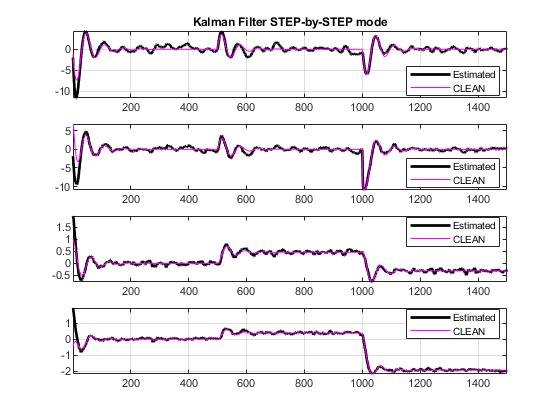

hold(hax(1), 'on');   plot(hax(1), x1_dot(2:(end-1)), '-m');   legend(hax(1), {'Estimated','CLEAN'},'Location','Best');
hold(hax(2), 'on');   plot(hax(2), x2_dot(2:(end-1)), '-m');   legend(hax(2), {'Estimated','CLEAN'},'Location','Best');
hold(hax(3), 'on');   plot(hax(3),     x1(2:(end-1)), '-m');   legend(hax(3), {'Estimated','CLEAN'},'Location','Best');
hold(hax(4), 'on');   plot(hax(4),     x2(2:(end-1)), '-m');   legend(hax(4), {'Estimated','CLEAN'},'Location','Best');

# **Local Subfunctions**

*ATTENTION:  local subfunctions can be placed at the very end of a script*

function LOC_plot_states(t, x1, x2, x1_dot, x2_dot)
    LIN_SPEC = '-r.';
    
    figure;
    subplot(2,2,1);
       plot(t, x1, LIN_SPEC);       xlabel('t (secs)'); 
                                   ylabel('X1 (m)'); grid('on'); 
                                   axis('tight');
                                   legend('X1', 'Location', 'best');
    %----------------------------------------------------------------------- 
    subplot(2,2,2);
       plot(t, x2, LIN_SPEC);  
                                   xlabel('t (secs)'); 
                                   ylabel('X2 (m)'); 
                                   grid('on'); axis('tight');
                                   legend('X2', 'Location', 'best');
    %-----------------------------------------------------------------------                               
    subplot(2,2,3);
       plot(t, x1_dot, LIN_SPEC);  
                                   xlabel('t (secs)'); 
                                   ylabel('X1 dot (m)'); 
                                   grid('on'); axis('tight');
                                   legend('X1 DOT', 'Location', 'best');
    %----------------------------------------------------------------------- 
    subplot(2,2,4);
       plot(t, x2_dot, LIN_SPEC);  
                                   xlabel('t (secs)'); 
                                   ylabel('X2 dot (m)'); 
                                   grid('on'); axis('tight');
                                   legend('X2 DOT', 'Location', 'best');

end
%-##########################################################################